% Base paths and clearing
clear all
clc
addpath functions/SETUP/
addpath functions/SENSE/
addpath functions/ACT/

% Setup Pi
[robotPi, blinkLED]= SETUP_pi("192.168.16.66");

% Setup Servos
robotServos = I2C_Servo_pHAT(robotPi);
% Setup Sensors
[adcDevice1, adcDevice2] = SETUP_adc(robotPi);

% Setup PiCam
robotCam = cameraboard(robotPi,'Resolution','320x240');
SETUP_piCam(robotCam);  

img = snapshotCustom(robotCam);

piCamWindow = figure('name','Robot Pi Camera','NumberTitle','off','Visible','on');
figure(piCamWindow)
imshow(img,'Border','tight')

ACT_moveRover(robotServos,0,0,0)

joy = vrjoystick(1);

disp("Drive Safely!")

Drive Safely!



sonarData = zeros(8,4);
IRData = zeros(8,6);

    0.3428    0.4391    0.3751



curve =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0016    0.0027    0.0045    0.0071    0.0108    0.0158    0.0222    0.0299    0.0388    0.0484    0.0579    0.0666    0.0737    0.0782    0.0798    0.0782    0.0737    0.0666    0.0579    0.0484    0.0388    0.0299    0.0222    0.0158    0.0108    0.0071    0.0045    0.0027    0.0016    0.0009    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


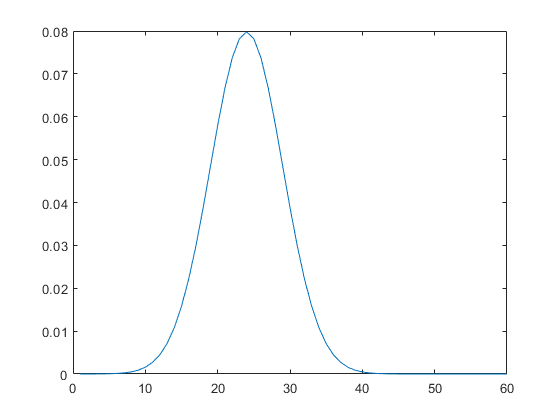

    0.1178    0.6959    0.6210



curve =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0016    0.0027    0.0045    0.0071    0.0108    0.0158    0.0222    0.0299    0.0388    0.0484    0.0579    0.0666    0.0737    0.0782    0.0798    0.0782    0.0737    0.0666    0.0579    0.0484    0.0388    0.0299    0.0222    0.0158    0.0108    0.0071    0.0045    0.0027    0.0016    0.0009    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


    0.5350    2.2809    0.7710



curve =     0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0016    0.0027    0.0045    0.0071    0.0108    0.0158    0.0222    0.0299    0.0388    0.0484    0.0579    0.0666    0.0737    0.0782    0.0798    0.0782    0.0737    0.0666    0.0579    0.0484    0.0388    0.0299    0.0222    0.0158    0.0108    0.0071    0.0045    0.0027    0.0016    0.0009    0.0005    0.0002    0.0001    0.0001    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000


    0.6961    0.1178    1.3066



curve =     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0002    0.0005    0.0009    0.0016    0.0027    0.0045    0.0071    0.0108    0.0158    0.0222    0.0299    0.0388    0.0484    0.0579    0.0666    0.0737    0.0782    0.0798    0.0782    0.0737    0.0666    0.0579    0.0484    0.0388    0.0299    0.0222    0.0158    0.0108    0.0071    0.0045    0.0027    0.0016


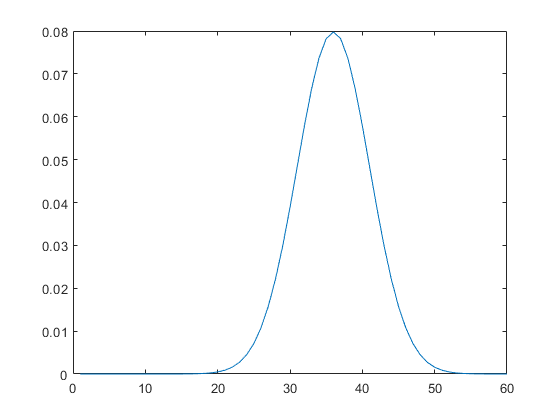

velocity = 0;
photoCount = 1;
sonarCount = 1;
IRCount = 1;
while 1
    % Take PiCam Photo
    if (1 == button(joy,1))
        piIMG = snapshotCustom(robotCam);            % capture a pi camera image
        figure(piCamWindow)                          % go to camWindow fo imshow
        imshow(piIMG,'Border',"tight")
        imwrite(piIMG, sprintf('images/Test2/Waypoint%g.jpg', photoCount), "jpg");
        photoCount = photoCount + 1;
    end
    
    if (1 == button(joy,6))
        ACT_moveCam(robotServos,90,40);
        
    end
    
    % Save Sonar Data
    if (1 == button(joy,2))
        curve = SENSE_IR(adcDevice1, adcDevice2)
        figure()
        plot(curve)
    end

    pause(.1)

end